# Transfer Learning Without DND

This script contains code to train the transfer learning model without deep network designer. You must run the solution script after line 19 to run this.

net = imagePretrainedNetwork("googlenet"); 
layers = net.Layers

layers =   143×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution        

## Resize Images to network Input Requirement

There are many ways to perform this process. The fastest is to use an augmentedImageDatastore, which will resize our imagedatastore in mini-batches as we pass images through the network for training.  

inputSize = net.Layers(1).InputSize(1:2);

augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize,imdsTest);

## Modify the Network

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

Remember the layers at the end of each network(the ones we talked about in MNIST)? Let's modify those to fit our needs.

- Fully Connected Layer - after all the convolution and max pooling layers, which detect features, this layer does the "high-level-reasoning" using its connection to all the activations in the previous layer.

- Softmax Layer - Computes the scores that a given image receives for each different category. 

classNames = categories(imds.Labels)

classNames = 5×1 cell array
    {'french_fries'}
    {'hamburger'   }
    {'hot_dog'     }
    {'pizza'       }
    {'sushi'       }


numClasses = numel(classNames);

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
    
net = replaceLayer(net,'loss3-classifier',newLearnableLayer);

## Set Training Options

Set the hyperparameters for this neural network.

initiallearnrate = 0.001;
valData          = augimdsValidation;
valDataPatience  = 3;
valDataFrequency = 25;
minibatchSize    = 32;
maxEpochs        = 5;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',valData,...
    'Plots','training-progress',...
    'MiniBatchSize', minibatchSize,...
    'MaxEpochs',maxEpochs,...
    'ValidationFrequency',valDataFrequency,...
    'ValidationPatience', valDataPatience, ...
    'Metrics','accuracy', ...
    'Verbose',false);

## Train and Validate the Network

Train the network with the training data and validate it with our validation data set (note: this is already set in the training options). If the validation results are not adequate, tune hyperparameters and try again.

Initialization may take a minute before training begins


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:07        0.001                             2.213                                     19.38
            1        1       00:00:07        0.001           3.116                                 9.375                      
           25        2       00:00:37        0.001         0.20793           0.32908                87.5                90.698
           50        3       00:01:05        0.001        0.093246           0.35617                 100                92.248
           75        4       00:01:31        0.001        0.091441           0.36493               93.75                90.698
           95        5       00:01:54        0.001        0.006347           0.34508                 100       

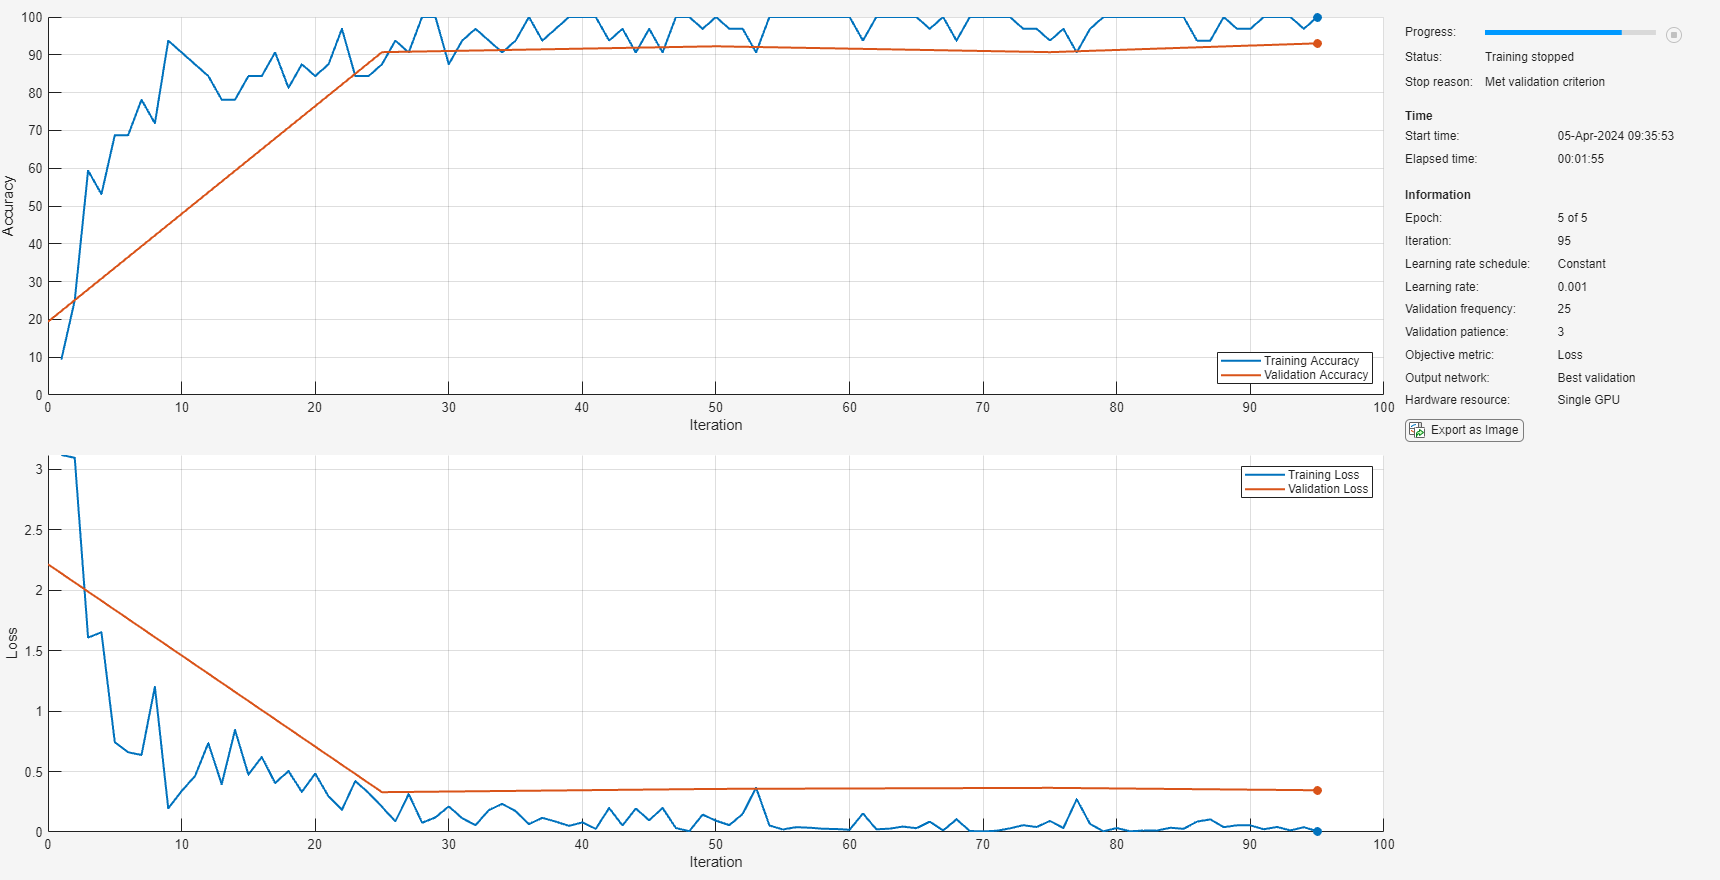

doTraining = true;

if doTraining
    disp('Initialization may take a minute before training begins');
    % use crossentropy loss function for classification
    net = trainnet(augimdsTrain, net, "crossentropy", trainOpts);
    % If you get out-of-memory error for GPU, go back to trainingOptions and reduce the 'MiniBatchSize'
else
    % load .mat file with trained network
    load('net_TransferLearning.mat')
end

*This ends the training section without DND. Please return to Work_TransferLearning.mlx.*

*Copyright 2024 The MathWorks, Inc.*